# Hands-On: Exercises on Predictors

## One-step Predictor of an MA(1) Stochastic Process

Consider the stationary process


$$v(t) = \xi(t) - \displaystyle \frac{1}{2}\,\xi(t-1) \quad \xi(\cdot) \sim \text{WN}\left(0,\, 16\right)$$


**Verify** that the model is in canonical form.

In fact, we have


$$\widehat{W}(z) = \displaystyle 1-\frac{1}{2}\,z^{-1} = \displaystyle \frac{z-\displaystyle \frac{1}{2}}{z}$$


Thus the optimal one-step predictor, fed by the data, is


$$W_1(z) = \displaystyle \frac{\displaystyle -\frac{1}{2}}{1-\displaystyle \frac{1}{2}\,z^{-1}} =
\displaystyle \frac{\displaystyle -\frac{1}{2}\,z}{z-\displaystyle \frac{1}{2}}$$


### The model of the Stochastic Process in MATLAB

Using MATLAB, we got

clear
close all
clc

var_xi = 16; % variance of the input white noise
mean_xi = 0; % mean value of the white noise

z = tf('z', 1);
hat_Wz = (z-1/2)/z % the filter using positive powers of "z"

hat_Wz =
 
  z - 0.5
  -------
     z
 
Sample time: 1 seconds
Discrete-time transfer function.



[Cz, Az] = tfdata(hat_Wz, 'v');

hat_Wz_1 = tf(Cz, Az, 1, 'Variable','z^-1') % the filter using powers of "z^-1"

hat_Wz_1 =
 
  1 - 0.5 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.



### Collecting Samples of a Process Realization

Let's generate some samples of a process realization and then collect $N$ of those samples. As usual, we skip the initial part of the collected data sequence to avoid any possible transient behavior:

Choose how many process data you want to simulate and collect:

Ndata = 460; 

Note: the model filter $\widehat{W}(z)$ han only one pole in $z=0$, so the transient is very short. The whitening filter has indeed only one pole in $z=\displaystyle \frac{1}2$

Let's estimate how long is the initial transient output of the whitening filter:

zero_threshold = 1e-8; 
% let's assume that the value is practically zero if less than or equal to zero_threshold
Ntransient = 5*(ceil(log10(zero_threshold)/log10(abs(0.5)))+10); 

N_TOT_data = Ndata + Ntransient;

Let's simulate the process and collect the samples

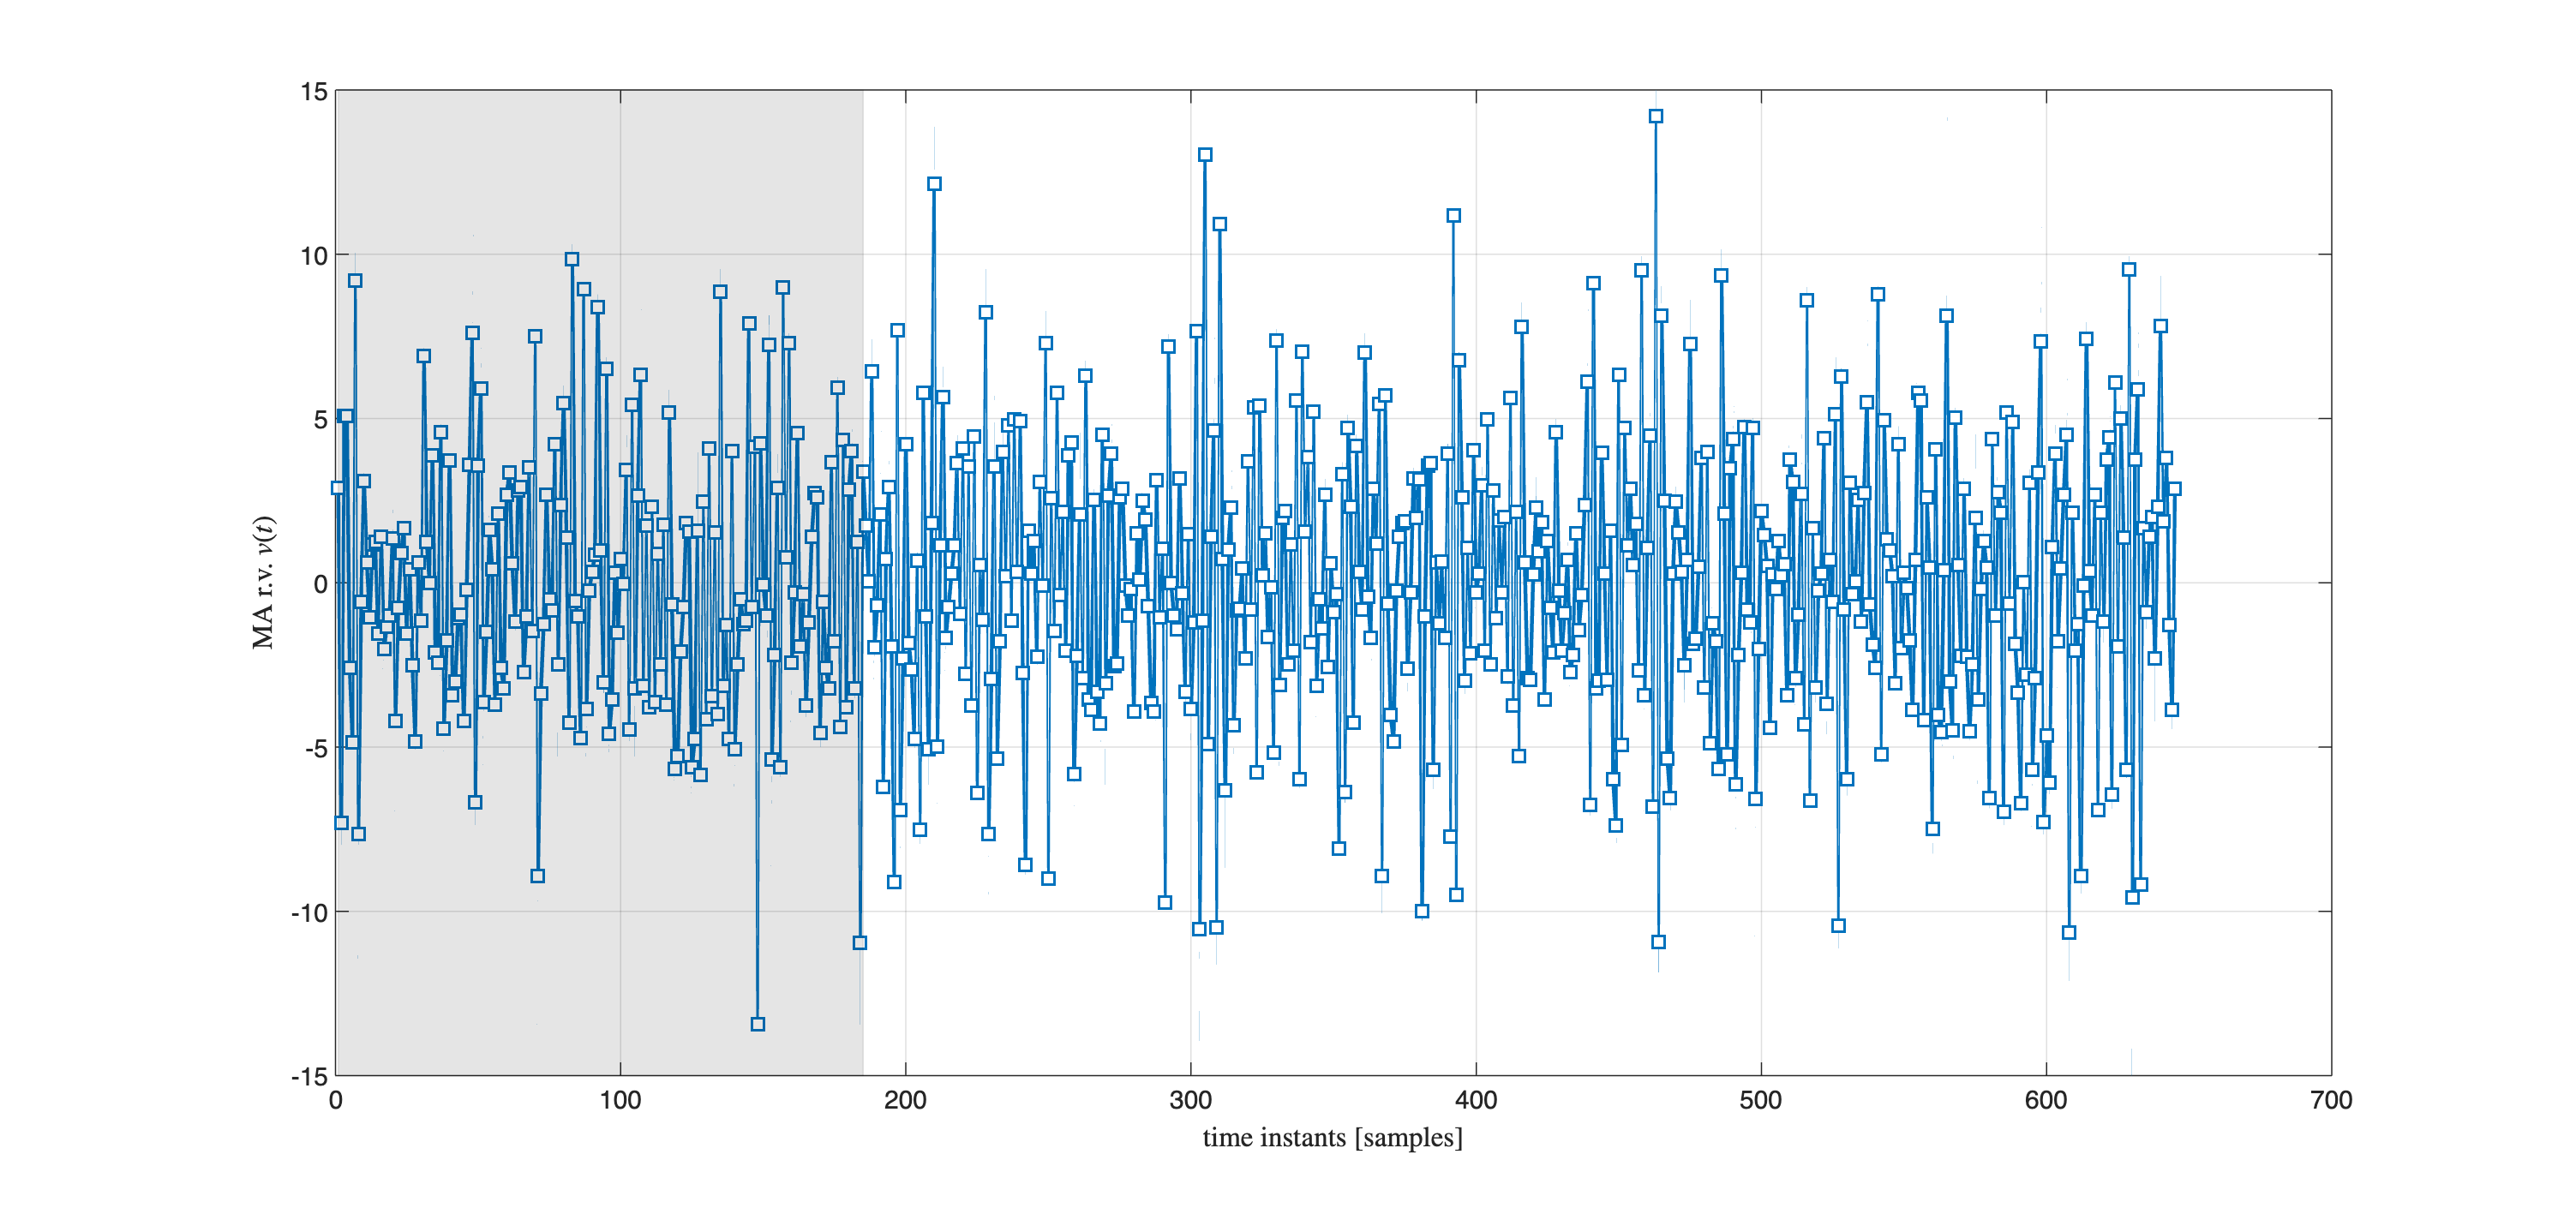

WN_samples = mean_xi + sqrt(var_xi)*randn(1, N_TOT_data);

[Cz1, Az1] = tfdata(hat_Wz_1, 'v'); 
% retrieving the coeff. arrays for the numerator and denominator using the
% notation with ascending powers of z^-1

V_MA_tot = filter(Cz1, Az1, WN_samples);

V_MA = V_MA_tot(Ntransient+1:end);

figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);
plot(V_MA_tot, 'Color', [0, 0.4470, 0.7410] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','square', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('MA r.v. $v(t)$', 'Interpreter','latex');

% the gray part corresponds to the transient part of the whitening filter response
YL = ylim;
fill([1 ,Ntransient(end), Ntransient(end), 1], [YL(1), YL(1), YL(2), YL(2)],...
       'k', 'FaceAlpha', 0.10, 'EdgeColor', 'k', 'EdgeAlpha', 0.10); 

### The One-Step Ahead Predictor from Data

% already known
% [Cz1, Az1] = tfdata(hat_Wz_1, 'v'); 

% one step of long division
[QQ,R] = poly_long_division(Cz1, Az1, 1)

QQ = 1

R =          0   -0.5000


Rz = R(2:end); % it is equivalent to multiplying the polynomial R(z) by z^(-1) -- see L11_OptimalPredictor.mlx

% --- 1-step ahead predictor (fed by white noise) ---      
hat_W1z_1 = tf(Rz, Az1, 1, 'Variable','z^-1') % using ascending powers of z^-1  

hat_W1z_1 =
 
  -0.5
 
Static gain.



Now we can describe the model of the prediction error as a $\text{WN}$ stationary process


$$E(z) = \hat{w}(0)=1$$


EzNUM = QQ;   % the MA model of the prediction error using ascending powers of z^-1
EzDEN = [1 0]; 
EzModel = tf(EzNUM, EzDEN, 1, 'Variable', 'z^-1')

EzModel =
 
  1
 
Static gain.



The **variance of the prediction error** is


$$\text{var}\left[\epsilon(t)\right] =  \text{var}\big[v\left(t+1\right)-\hat{v}\left(t+1\vert t\right) \big]= \left[\displaystyle 1 \right]\cdot \lambda^2_{\xi}$$


pred_err_var = EzNUM*EzNUM'*var_xi % prediction error variance

pred_err_var = 16

% the predictor, fed by data - notation using powers of z^-1
W1z_1 = tf(Rz, Cz1, 1, 'Variable','z^-1') % <-- the predictor from data

W1z_1 =
 
      -0.5
  ------------
  1 - 0.5 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.



% retrieving the arrays with the coeffs of polynomials
[numW_1, denW_1] = tfdata(W1z_1, 'v');

% using the other possible notation --> notation using powers of z
Wz_1 = tf(numW_1, denW_1, 1, 'Variable', 'z') % <-- the predictor from data  

Wz_1 =
 
  -0.5 z
  -------
  z - 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.




zpk(Wz_1) % different notation: zeros, poles and gain

ans =
 
  -0.5 z
  -------
  (z-0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



#### Comparing the Prediction with the Observed Data

% already known
% [numW_1, denW_1] = tfdata(W1z_1, 'v');

% build the predictor filter and apply it to the collected data
hatV_1stepP_tot = filter(numW_1, denW_1, V_MA_tot);

hatV_1stepP = hatV_1stepP_tot(Ntransient+1:end);

Plot the prediction and compare with the data:

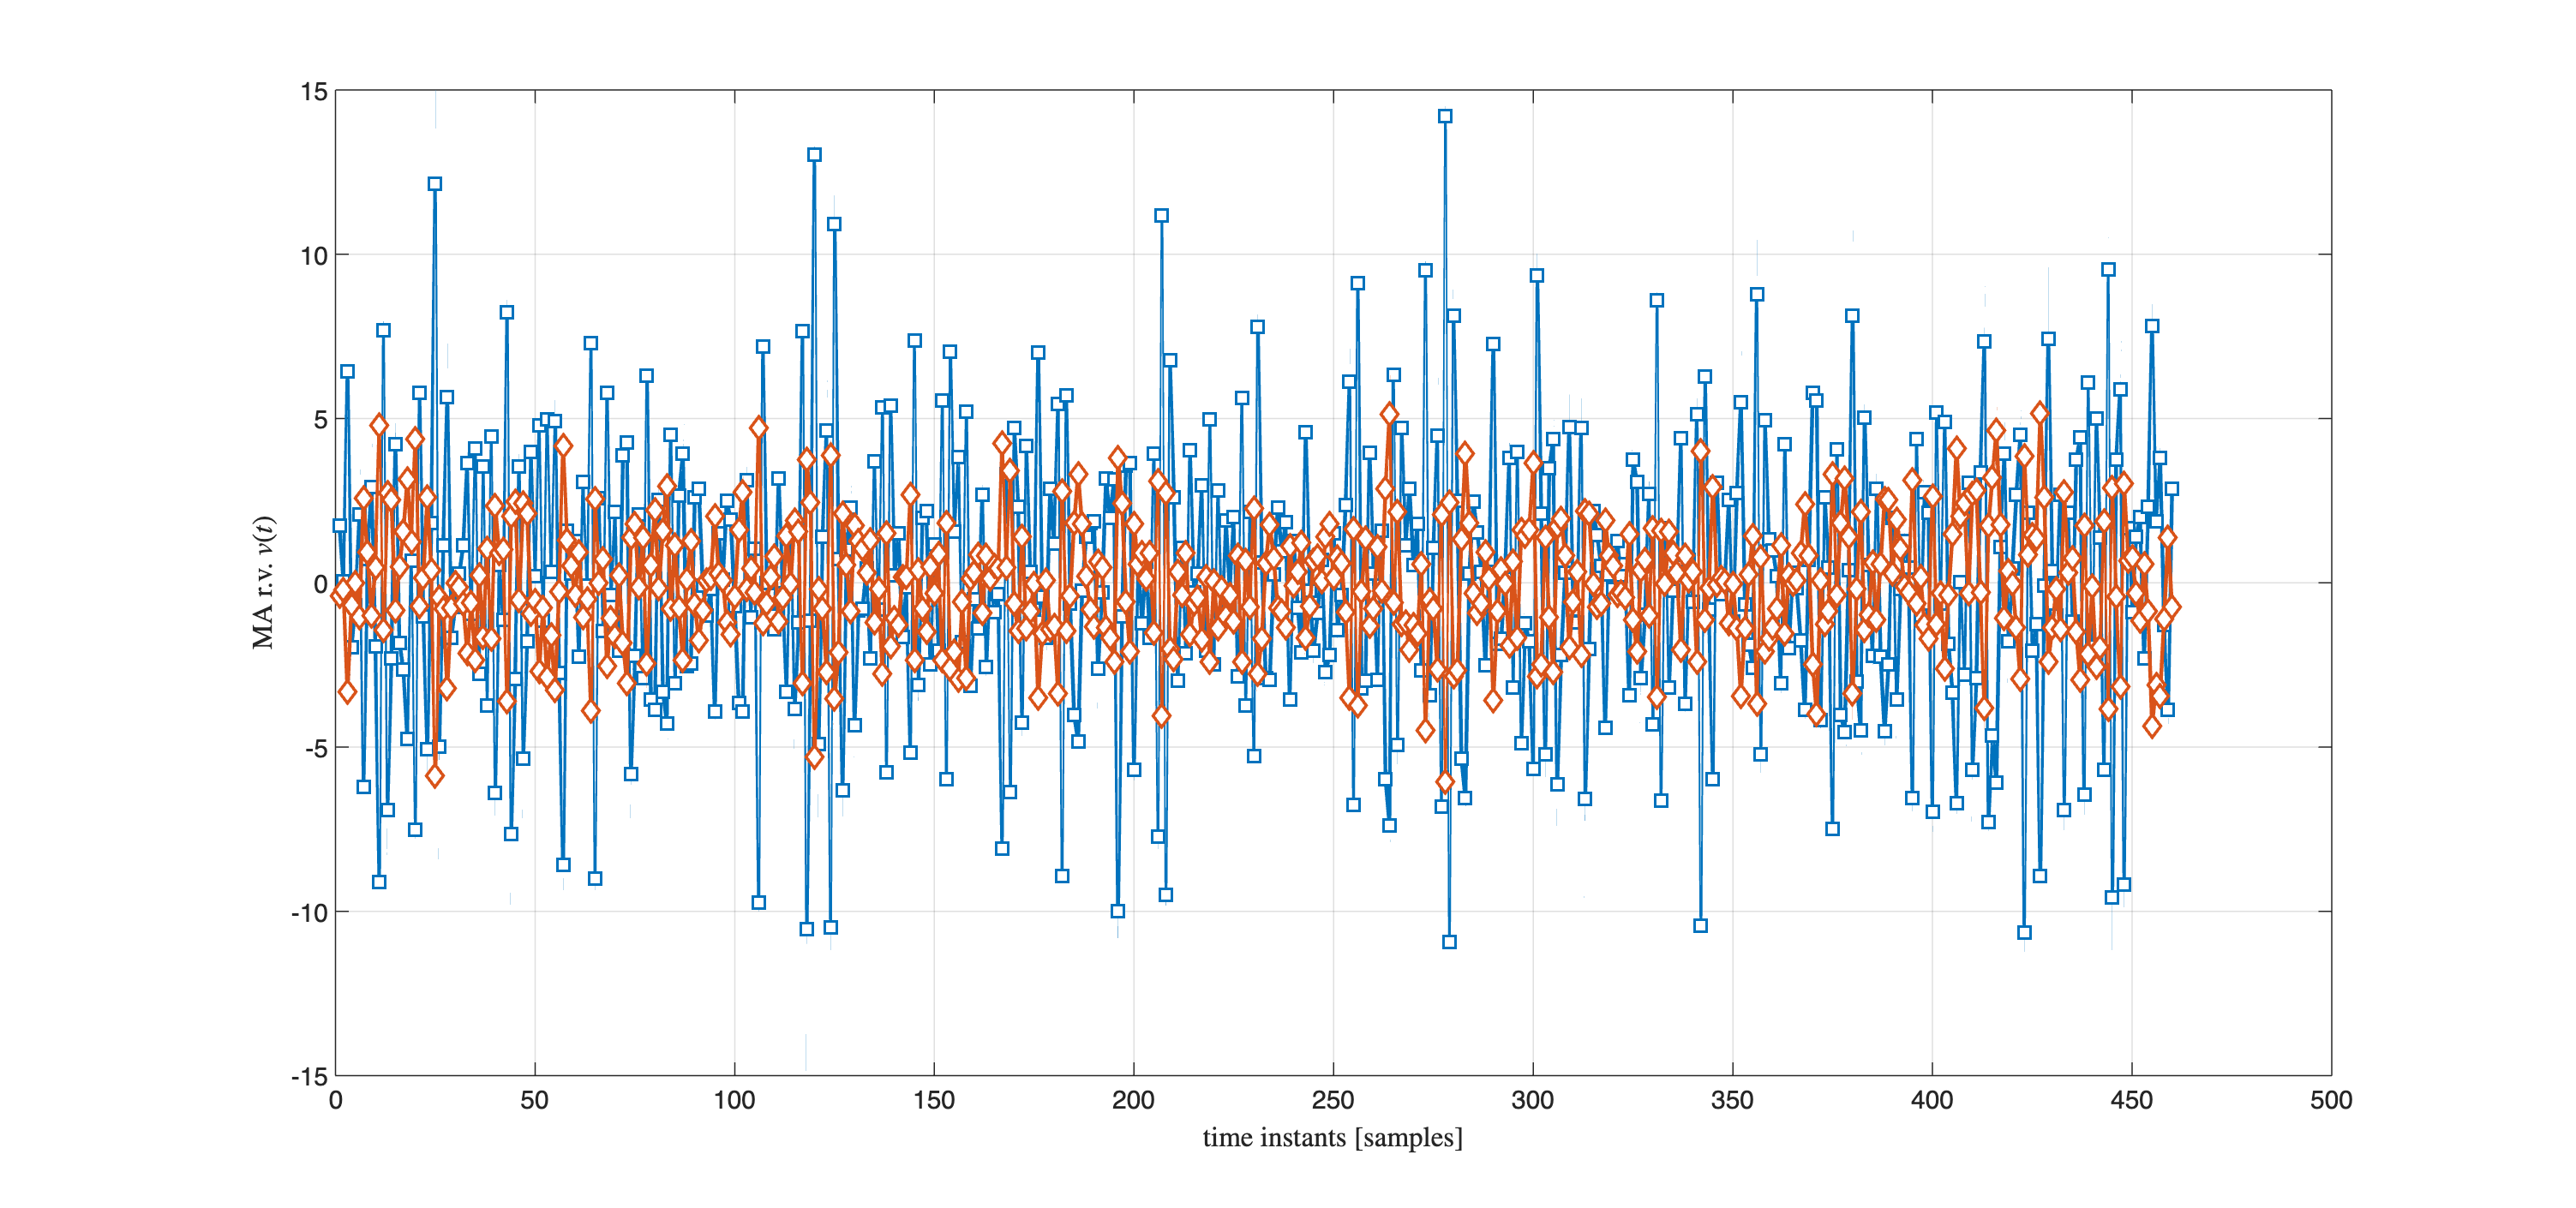

figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);

plot(V_MA, 'Color', [0, 0.4470, 0.7410] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','square', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('MA r.v. $v(t)$', 'Interpreter','latex');

plot(hatV_1stepP, 'Color', [0.8500 0.3250 0.0980] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','diamond', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');

## One-step Predictor of an ARMA Process, not in Canonical Form 

Consider the $ARMA$ stationary process described by the model


$$\begin{array}{c}
v(t)+\frac{5}{6} v(t-1)+\frac{1}{6} v(t-2)=
\eta(t)+\frac{10}{9} \eta(t-1) \quad \eta(\cdot) \sim \text{WN}\left(0,\,1\right) \\[1em]
\left(1 + \frac{5}{6} z^{-1} + \frac{1}{6} z^{-2}\right) v(t) = \left(1 + \frac{10}{9} z^{-1}\right) \eta(t)\\[1em]
v(t) = \displaystyle \frac{\displaystyle \left(1 + \frac{10}{9} z^{-1}\right)}{\displaystyle \left(1 + \frac{5}{6} z^{-1} + \frac{1}{6} z^{-2}\right) } \eta(t) \quad (\star)
\end{array}$$


The assumptions of the spectral factorization theorem are **NOT** satisfied because the poles are $\, -\frac{1}{2}, -\frac{1}{3} \,$ but the zeros are $\, 0, -\frac{10}{9} \,$ . In fact


$$\widehat{W}(z) = \displaystyle \frac{\displaystyle \left(1 + \frac{10}{9} z^{-1}\right)}{\displaystyle \left(1 + \frac{5}{6} z^{-1} + \frac{1}{6} z^{-2}\right) }  = \displaystyle \frac{\displaystyle z\, \left(z + \frac{10}{9} \right)}{\displaystyle \left(z^2 + \frac{5}{6} z + \frac{1}{6}\right) }$$


So

- let's obtain the canonical spectral form of the given process. 

- then determine the one-step predictor.

Let's define the process model using MATLAB

clear 
close all
clc

z = tf('z',1);

Wz = z*(z+10/9)/(z^2+5*z/6+1/6)  % the LTI system

Wz =
 
  6 z^2 + 6.667 z
  ---------------
  6 z^2 + 5 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



[Bz, Az] = tfdata(Wz, 'v');      % the polynomials coefficients, ordered in deecreasing powers of "z"

Az = Az ./Az(1) % the denominator is now a monic polynomial

Az =     1.0000    0.8333    0.1667


Bz = Bz./Az(1)  % scaling both the polynomials

Bz =     6.0000    6.6667         0



sigma2_eta = 1; % the variance of the white noise 


### The Spectral Canonical Form

Given the LTI system $\widehat{W}(z)$ (the filter)


$$\widehat{W}(z) = \displaystyle \frac{b(z)}{a(z)} = \displaystyle \frac{b_0\, z^n+b_1\, z^{n-1} + \cdots +b_{n-1} \, z+b_n}{z^n+a_1 \, z^{n-1} + \cdots +a_{n-1}\, z +a_n} $$


 and the zero-mean white noise $\eta(t)$ (with variance $\lambda^2_{\eta}$), then the spectrum $\Phi_{v}(z)$ can be expressed as


$$\Phi_{v}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \Phi_{\eta}(z) = W(z) \cdot W\left(\displaystyle \frac{1}{z} \right) \cdot \lambda^2_{\eta} =  \displaystyle \frac{\beta(z)}{\alpha(z)} = \displaystyle \frac{\displaystyle \sum_{k=-m}^{m}\, \beta_k\,z^k}{\displaystyle \sum_{k=-n}^{n}\,\alpha_k\,z^k}$$


with


$$\left\{
\begin{array}{lcl}
\alpha_p = \alpha_{-p} &\quad& p=-n\,,\,-n+1\,,\, \cdots ,\, n-1\,,\, n \\
\beta_q = \beta_{-q} &\quad& q=-m\,,\,-m+1\,,\, \cdots ,\, m-1\,,\, m \\
\alpha_n \ne 0 \,,\; \beta_m \ne 0 &\quad& \text{i.e. both polynomials are symmetric polynomials in $z$ and $z^{-1}$} \\
\Phi\left(e^{i\,\omega} \right) \ge 0 \; \forall \omega& \quad &\text{i.e. $\Phi(z)$ is a rational spectrum}
\end{array}
\right.$$


In fact,


$$\begin{array}{rcl}
\Phi_{v}(z) &=& \displaystyle W(z) \cdot W\left(z^{-1}\right) \cdot \lambda^2_{\eta} = \displaystyle \frac{b(z)}{a(z)} \cdot \frac{b\left(z^{-1}\right)}{a\left(z^{-1}\right) }\cdot \lambda^2_{\eta} \\
 &=& \displaystyle \frac{b_0\, z^n+b_1\, z^{n-1} + \cdots +b_{n-1} \, z+b_n}{z^n+a_1 \, z^{n-1} + \cdots +a_{n-1}\, z +a_n}  \cdot   
 \displaystyle \frac{b_0\, z^{-n}+b_1\, z^{-(n-1)} + \cdots +b_{n-1} \, z^{-1}+b_n}{z^{-n}+a_1 \, z^{-(n-1)} + \cdots +a_{n-1}\, z^{-1} +a_n} 
\cdot  \lambda^2_{\eta} \\
 &=& \displaystyle \frac{\beta_0+\beta_1\,\left(z+z^{-1}\right)+ \cdots + \beta_n\,\left(z^n+z^{-n}\right)}{1+\alpha_1\,\left(z+z^{-1}\right)+\cdots + \alpha_n\,\left(z^n+z^{-n}\right)} = \displaystyle \frac{\beta(z)}{\alpha(z)}
\end{array}$$


where


$$\left\{
\begin{array}{rclll}
\alpha_i &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} a_k\,a_{k+i}}{\displaystyle \sum_{k=0}^{n} a_k^2} &,& i=1,\,2,\,\ldots ,\,n \quad \alpha_0 = 1 \\
\\
\beta_j &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} b_k\,b_{k+j}}{\displaystyle \sum_{k=0}^{n} a_k^2} \cdot \lambda^2_{\eta} &,& j=0,\,1,\,2,\,\ldots ,\,n 
\end{array}
\right.$$


#### First Step

Evaluating ${\displaystyle \sum_{k=0}^{n} a_k^2} $

sum_ak2 = sum(Az.^2)

sum_ak2 = 1.7222

#### Second Step: Evaluating the Coefficients of the Symmetrical Polynomial in the Denominator

Evaluating $\begin{array}{rclll}
\alpha_i &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} a_k\,a_{k+i}}{\displaystyle \sum_{k=0}^{n} a_k^2} &,& i=1,\,2,\,\ldots ,\,n
\end{array}$

alphaPoly = zeros(size(Az));
alphaPoly(1) = 1; % by construction alpha_0 = 1
N = numel(Az)-1;
for i=2:N+1
    i
    dummy_alpha_i = 0;
    for k=1:N
        if ((k+i-1)<=N+1)
            dummy_alpha_i = dummy_alpha_i+Az(k)*Az(k+i-1);
        end
    end % for k
    alphaPoly(i) = dummy_alpha_i/sum_ak2;
end % for i

i = 2

i = 3

disp(alphaPoly)

    1.0000    0.5645    0.0968


#### Third step: Evaluation of the Coefficients of the Symmetrical Polynomial at the Numerator

Evaluating $\begin{array}{rclll}
\beta_j &=& \displaystyle \frac{\displaystyle \sum_{k=0}^{n-1} b_k\,b_{k+j}}{\displaystyle \sum_{k=0}^{n} a_k^2} \cdot \lambda^2_{\eta} &,& j=0,\,1,\,2,\,\ldots ,\,n 
\end{array}$

betaPoly = zeros(size(Az));


for j=1:N+1
    dummy_beta_j = 0;
    for k=1:N
        if ((k+j-1)<=N+1)
            dummy_beta_j = dummy_beta_j+Bz(k)*Bz(k+j-1);
        end
    end % for k
    betaPoly(j) = sigma2_eta*dummy_beta_j/sum_ak2;
end % for i
disp(betaPoly)

   46.7097   23.2258         0


**Note**: if the last element in the symmetrical polynomial $\beta(z)$ is equal to $0$, then the actual degree of the polynomial $\beta(z)$ is less than $n$: 

betaPoly = betaPoly(1:2); % updating the array with the coeffs of beta(z), starting from beta_0 to beta_(n-1) now

#### Final Step: Applying the Spectral Factorization Algorithm

Now we re ready to apply the *Spectral Factorization Algorithm*. 

Given the description of both the polynomials $\beta(z)$ and $\alpha(z)$ as symmetric polynomials, we can obtain the spectral factorization simply using the live function `L8_spectrFactAlg()`


% ========= Important Remark ==========
% The function L8_spectrFactAlg() allows 
% the spectral factorisation of a rational 
% spectrum to be calculated.
% ---
% Inputs:
% betaP  <--> the coefficients of the symmetric polynomial beta(z+z^(-1)),
%             ordered from beta_n to beta_0
% alphaP <--> the coefficients of the symmetric polynomial alpha(z+z^(-1)),
%             ordered from alpha_n to alpha_0 (=1)
% ---
% Outputs:
% Az <--> the monic Hurwitz polynomial 1+a_1 z^(-1)+...a_n z^(-n_) -- the
%         roots of Az have magnitude stricly less than 1
% Cz <--> the monic polynomial 1+c_1 z^(-1)+...c_n z^(-n_); the roots of Cz
%         have magnitude less or equal to 1
% r  <--> the variance of the white noise feeding-in the filter with
%         transfer function W(z) = Cz/Az

[r, Cz_coeffs, Az_coeffs] = L8_spectrFactAlg(fliplr(betaPoly), fliplr(alphaPoly))

r = 44.4444

Cz_coeffs =     1.0000    0.9000


Az_coeffs =     1.0000    0.8333    0.1667


The white noise of the spectral canonical form is a zero-mean noise with variance

mean_xi=0;
var_xi = r

var_xi = 44.4444

Finally, the spectral canonical form of the LTI filter $W(z)$ is

hat_Wz_1 = tf(Cz_coeffs, Az_coeffs, 1, 'Variable','z^-1')

hat_Wz_1 =
 
          1 + 0.9 z^-1
  -----------------------------
  1 + 0.8333 z^-1 + 0.1667 z^-2
 
Sample time: 1 seconds
Discrete-time transfer function.




pW_1 = pole(hat_Wz_1)

pW_1 =    -0.5000
   -0.3333



zW_1 = zero(hat_Wz_1)

zW_1 =          0
   -0.9000


### Collecting Samples of a Process Realization

Let's generate some samples of a process realization and then collect $N$ of those samples. As usual, we skip the initial part of the collected data sequence to avoid any possible transient behavior.

Choose how many process data you want to simulate and collect:

Ndata = 740; 

Note: the model filter $\widehat{W}(z)$ han two real poles in $p_1=-\displaystyle \frac{1}{2}\;,\quad p_2 = =-\displaystyle \frac{1}{3}$. The whitening filter has indeed two real poles in $p_{1\,w}=\displaystyle 0\;,\quad p_{2\,w} = -\displaystyle \frac{9}{10}$

Let's estimate how long is the initial transient output of the whitening filter:

p_vector = pole(hat_Wz_1); % the poles of W(z)
z_vector = zero(hat_Wz_1); % the zeros of W(z)

slowest_pole = max(abs(p_vector));
slowest_pole_whitening = max(abs(z_vector));

zero_threshold = 1e-8; 
% let's assume that the value is practically zero if less than or equal to zero_threshold
Ntransient1 = 10*(ceil(log10(zero_threshold)/log10(slowest_pole))+10); % a very raw estimation
Ntransient2 = 10*(ceil(log10(zero_threshold)/log10(slowest_pole_whitening))+10); % a very raw estimation
Ntransient = max(Ntransient1, Ntransient2)

Ntransient = 1850


N_TOT_data = Ndata + Ntransient;

WN_samples = mean_xi + sqrt(var_xi)*randn(1, N_TOT_data);

[Cz1, Az1] = tfdata(hat_Wz_1, 'v'); 
% retrieving the coeff. arrays for the numerator and denominator using the
% notation with ascending powers of z^-1

V_ARMA_tot = filter(Cz1, Az1, WN_samples);

V_ARMA = V_ARMA_tot(Ntransient+1:end);

### Plot the Process Data

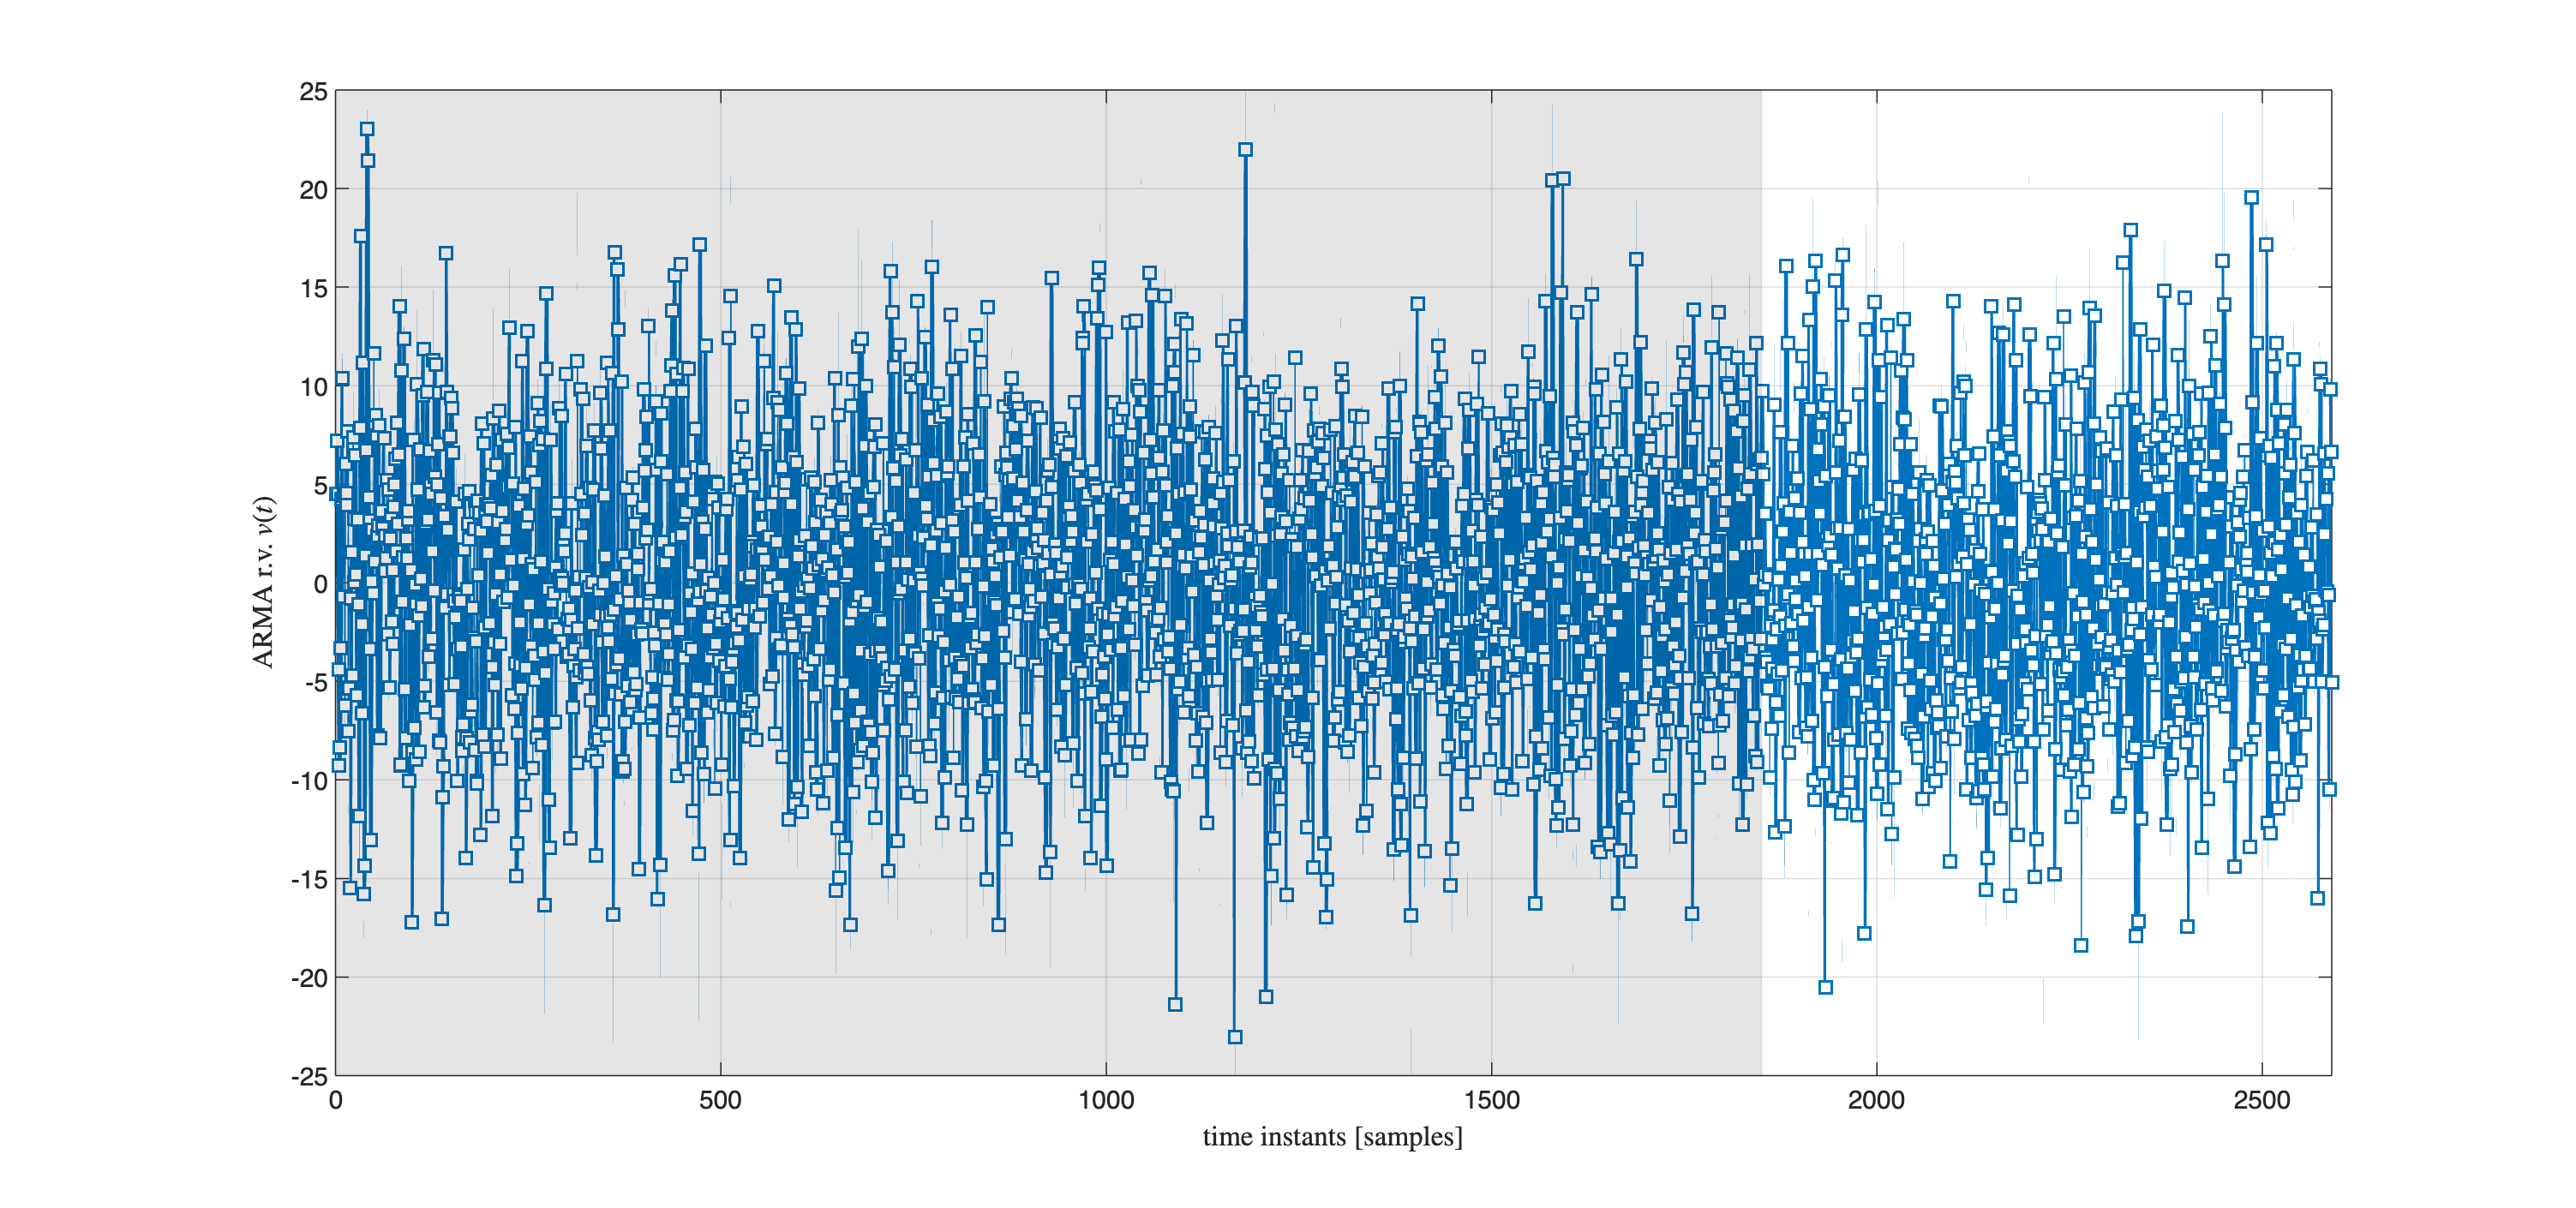

figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);
plot(V_ARMA_tot, 'Color', [0, 0.4470, 0.7410] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','square', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('ARMA r.v. $v(t)$', 'Interpreter','latex');
xlim([0, numel(V_ARMA_tot)]); % adjusting the x-axis limits
% the gray part corresponds to the transient part of the whitening filter response
YL = ylim;
fill([1 ,Ntransient(end), Ntransient(end), 1], [YL(1), YL(1), YL(2), YL(2)],...
       'k', 'FaceAlpha', 0.10, 'EdgeColor', 'k', 'EdgeAlpha', 0.10); 

### The One-Step Ahead Predictor from Data

% already known
% [Cz1, Az1] = tfdata(hat_Wz_1, 'v'); 

% one step of long division
[QQ,R] = poly_long_division(Cz1, Az1, 1)

QQ = 1

R =          0    0.0667   -0.1667


Rz = R(2:end); % it is equivalent to multiplying the polynomial R(z) by z^(-1) -- see L11_OptimalPredictor.mlx

% --- 1-step ahead predictor (fed by white noise) ---      
hat_W1z_1 = tf(Rz, Az1, 1, 'Variable','z^-1') % using ascending powers of z^-1  

hat_W1z_1 =
 
      0.06667 - 0.1667 z^-1
  -----------------------------
  1 + 0.8333 z^-1 + 0.1667 z^-2
 
Sample time: 1 seconds
Discrete-time transfer function.



Now we can describe the model of the prediction error as a $\text{WN}$ stationary process


$$E(z) = \hat{w}(0)=1$$


EzNUM = QQ;   % the MA model of the prediction error using ascending powers of z^-1
EzDEN = [1 0]; 
EzModel = tf(EzNUM, EzDEN, 1, 'Variable', 'z^-1')

EzModel =
 
  1
 
Static gain.



The **variance of the prediction error** is


$$\text{var}\left[\epsilon(t)\right] =  \text{var}\big[v\left(t+1\right)-\hat{v}\left(t+1\vert t\right) \big]= \left[\displaystyle 1 \right]\cdot \lambda^2_{\xi}$$


pred_err_var = EzNUM*EzNUM'*var_xi % <--- prediction error variance

pred_err_var = 44.4444



% ---> the predictor, fed by data - notation using powers of z^-1 <----
W1z_1 = tf(Rz, Cz1, 1, 'Variable','z^-1') % <-- the predictor from data

W1z_1 =
 
  0.06667 - 0.1667 z^-1
  ---------------------
      1 + 0.9 z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.



% retrieving the arrays with the coeffs of polynomials
[numW_1, denW_1] = tfdata(W1z_1, 'v');

% using the other possible notation --> notation using powers of z
Wz_1 = tf(numW_1, denW_1, 1, 'Variable', 'z') % <-- the predictor from data  

Wz_1 =
 
  0.06667 z - 0.1667
  ------------------
       z + 0.9
 
Sample time: 1 seconds
Discrete-time transfer function.




zpk(Wz_1) % different notation: zeros, poles and gain

ans =
 
  0.066667 (z-2.5)
  ----------------
      (z+0.9)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.



#### Comparing the Prediction with the Observed Data

% already known
% [numW_1, denW_1] = tfdata(W1z_1, 'v');

% build the predictor filter and apply it to the collected data
hatV_1stepP_tot = filter(numW_1, denW_1, V_ARMA_tot);

hatV_1stepP = hatV_1stepP_tot(Ntransient+1:end);

Plot the prediction and compare with the data:

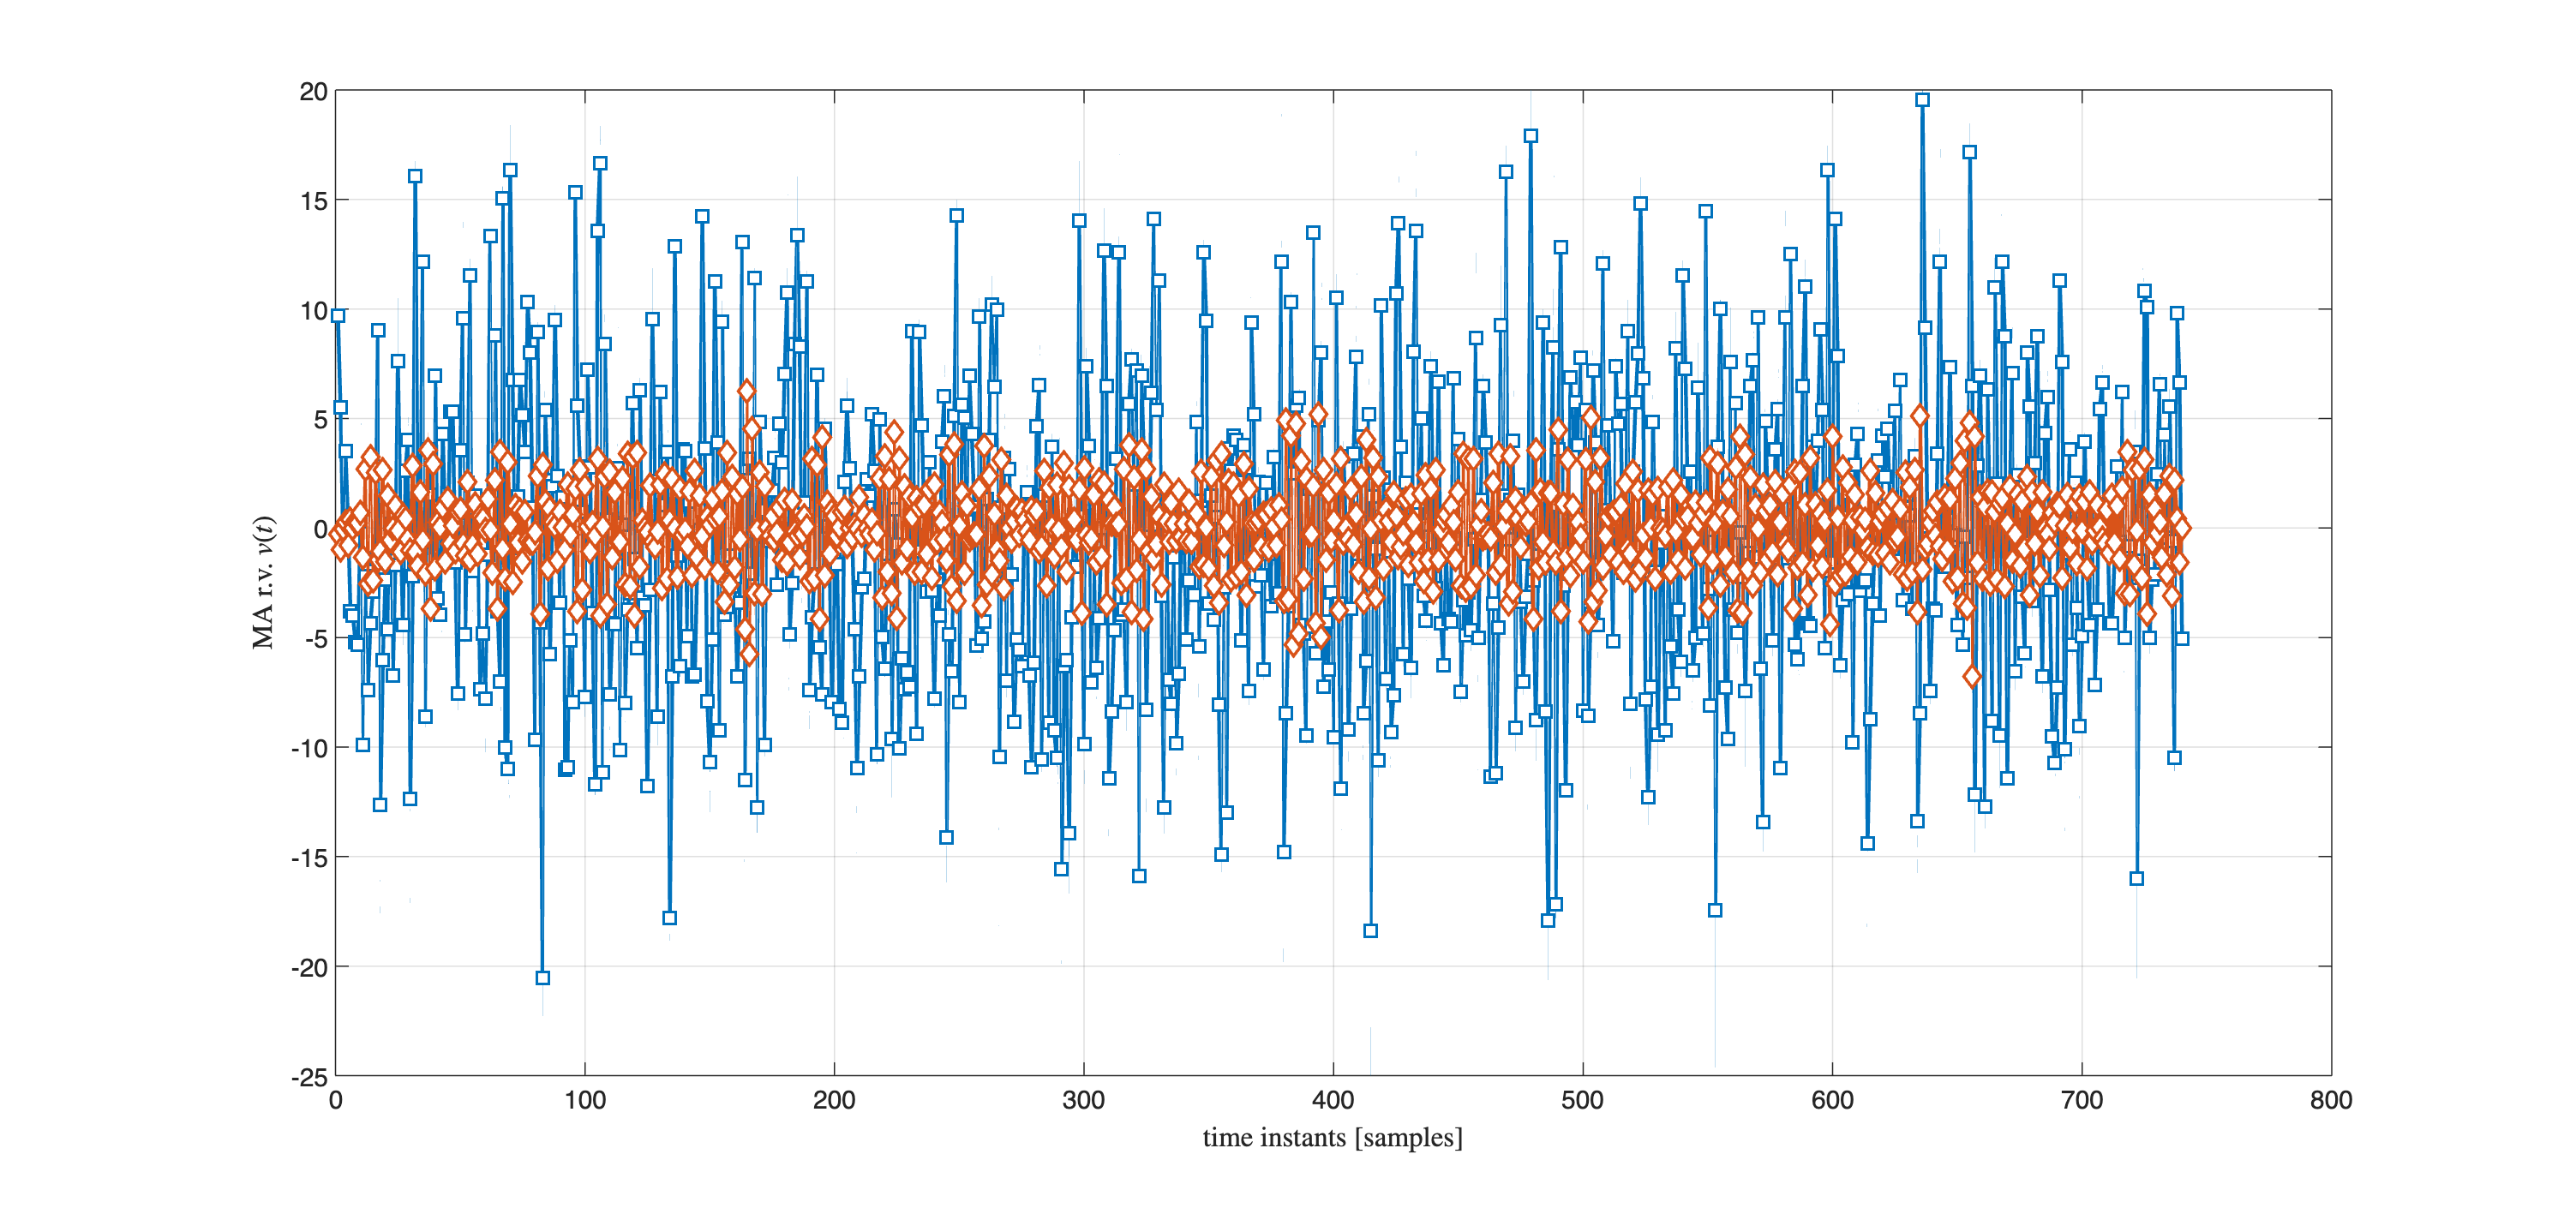

figure('Units','normalized', 'Position', [0.1, 0.1, 0.9, 0.75]);

plot(V_ARMA, 'Color', [0, 0.4470, 0.7410] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','square', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');
grid on; hold on;
xlabel('time instants [samples]', 'Interpreter','latex');
ylabel('MA r.v. $v(t)$', 'Interpreter','latex');

plot(hatV_1stepP, 'Color', [0.8500 0.3250 0.0980] , 'LineWidth', 1.5, 'LineStyle','-', 'Marker','diamond', ...
      'MarkerSize', 6, 'MarkerEdgeColor','auto', 'MarkerFaceColor','auto');